clc; clf; clearvars;

%Genera el número de cargas tanto positivas como negativas
numeroCargas = 5;
qPos = 1:numeroCargas;
qNeg = qPos;


#### Graficar placas

Width = 2;
Height = 20; %Tamaño placa Positiva
xRect = -9;

%Positiva
BoxPlot3(xRect,0,-Height/2,Width,Width,Height,[1 0 0])
hold on;

%Negativa
Height_Neg = 15; %Tamaño placa Negativa
BoxPlot3(-xRect,0,-Height_Neg/2,Width,Width,Height_Neg,[0 0 1])


#### Graficar posición de cargas

posicionQ_pos = linspace(-Height/2,Height/2,length(qPos)+2);
posicionQ_neg = linspace(-Height_Neg/2,Height_Neg/2,length(qNeg)+2);
for charge = 2:length(posicionQ_pos)-1
    text(xRect-0.75,Width/2,posicionQ_pos(charge)+0.5,'+','FontSize',20,'Color','white')
    text(-xRect-0.8,Width/2,posicionQ_neg(charge)+0.5,'-','FontSize',30,'Color','white')
end


#### Crear un globulo rojo

n = 25;

%aleatoria randi ([1 5],1, 1) limite inferior y superior, una fila y una
%columna
xc = randi([-9 10],1,1) %movimiento en x

xc = -4

yc= randi([1 9],1,1) %movimiento en y

yc = 5

zc = randi([1 7],1,1); %movimiento en z

xr = 2;
yr = 1;
zr=2;


[x,y,z]= ellipsoid(xc,yc,zc,xr,yr,zr,n);
mycolors = [1 0 0; 1 0 0; 1 0 0];
colormap(mycolors);
axis equal
surf(x,y,z)



#### Signo de infección por malaria

if xc > 0
    tex = text(11,9,10,'Infectado por Malaria','FontSize',18,'Color','r','EdgeColor','k');
else 
   tex = text(11,9,10, 'No infectado por Malaria', 'Fontsize', 18, 'Color','g', 'EdgeColor', 'k'); 
    
end



    
    





#### Crear el campo Vectorial

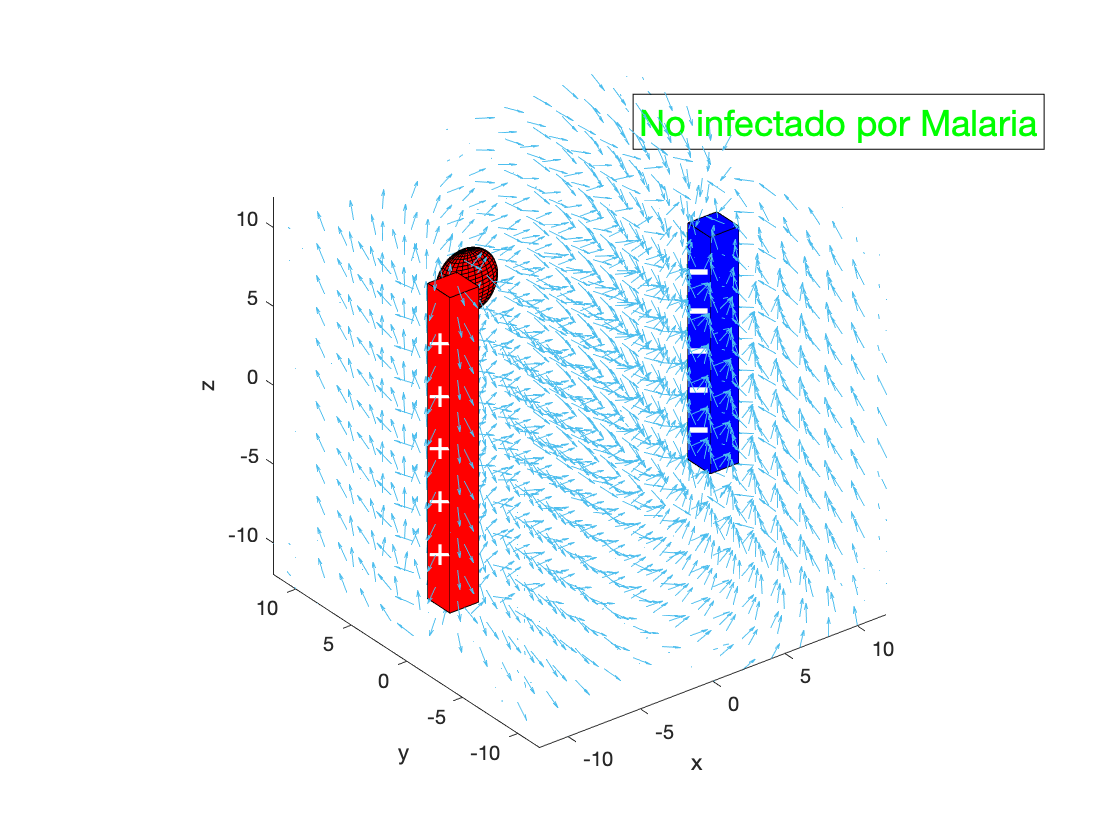

X = -20:2:20;
Y = -20:2:20;
Z = -20:2:20;
[x,y,z] = meshgrid(X,Y,Z);


%Campo eléctrico inicializado en 0
Ex = 0;
Ey = 0;
Ez = 0;

%Valores constantes
Qn_magnitude = -20; %Magnitud de la carga negativa
eps0 = 8.854e-12;
kC = 1/(4*pi*eps0);
xPosition = xRect+1;
YPosition = Width/2;

%Ciclo que calcula el campo vectorial de las cargas negativas
for Qn = 1:length(qNeg)

    Rx = x - (-xPosition);
    Ry = y - YPosition;
    Rz = z - posicionQ_neg(Qn+1);
    R = sqrt(Rx.^2 + Ry.^2 + Rz.^2).^3;
    Ex = Ex + kC .* Qn_magnitude .* Rx ./ R;
    Ey = Ey + kC .* Qn_magnitude .* Ry ./ R;
    Ez = Ez + kC .* Qn_magnitude .* Ry ./ R;
end

Qpos_magnitude = 20; %Magnitud de la carga positiva

%Ciclo que calcula el campo vectorial de las cargas positivas
for Qpos = 1:length(qNeg)

    Rx = x - (xPosition);
    Ry = y - YPosition;
    Rz = z - posicionQ_pos(Qpos+1);
    R = sqrt(Rx.^2 + Ry.^2 + Rz.^2).^3;
    Ex = Ex + kC .* Qpos_magnitude .* Rx ./ R;
    Ey = Ey + kC .* Qpos_magnitude .* Ry ./ R;
    Ez = Ez + kC .* Qpos_magnitude .* Ry ./ R;
end
%Se normaliza el vector para que todos sean del mismo tamaño
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2); %Magnitud vector del campo vectorial

u = Ex./E;
v = Ey./E;
w = Ez./E;

%Grafica vectores 
quiver3(x,y,z,u,v,w,'AutoScaleFactor',0.6) %AutoScale sirve para hacer los vectores más pequeños y mejor apreciables
xlim([-12 12]); ylim([-12 12]); zlim([-12 12]);
xlabel('x'); ylabel('y'); zlabel('z');

Función para graficar cajas en 3D

function BoxPlot3(x0, y0, z0, Lx, Ly, Lz,color)
    x = [x0, x0, x0, x0, x0+Lx, x0+Lx, x0+Lx, x0+Lx]; %(1×8)
    y = [y0, y0, y0+Ly, y0+Ly, y0, y0, y0+Ly, y0+Ly]; 
    z = [z0, z0+Lz, z0+Lz, z0, z0, z0+Lz, z0+Lz, z0];

    index = zeros(6,5);
    index(1,:) = [1 2 3 4 1];
    index(2,:) = [5 6 7 8 5];
    index(3,:) = [1 2 6 5 1];
    index(4,:) = [4 3 7 8 4];
    index(5,:) = [2 6 7 3 2];
    index(6,:) = [1 5 8 4 1];
    for k = 1:6
        fill3(x(index(k,:)), y(index(k,:)), z(index(k,:)),color)        
        hold on
    end
end